## Decision Branching

 This code creates a random number to test the if statement.

doPlot = randi([0 1])

doPlot = 1

This code loads the data.

load datafile
Elements

Elements = 7×4 table
      Element      Density    Volume1    Volume2
    ___________    _______    _______    _______

    "Lithium"       0.53      4.0753        NaN 
    "Argon"         1.78      6.6678     2.1328 
    "Potassium"     0.86      1.5177     3.6852 
    "Calcium"        1.6      3.6375     8.5389 
    "Scandium"         3      4.7243     10.157 
    "Vanadium"      6.11      9.0698     2.8739 
    "Strontium"     2.54      5.3002     4.4508 


Elements.Element

ans = 7×1 string array
    "Lithium"
    "Argon"
    "Potassium"
    "Calcium"
    "Scandium"
    "Vanadium"
    "Strontium"


density = data(:,1)

density =     0.5300
    1.7800
    0.8600
    1.6000
    3.0000
    6.1100
    2.5400


**Task 1 **

The body of an if block executes only if the condition is true.

You can check for equality by using the == operator.

if x == 0.5

    y = 3

end

**Task**

Modify the script so that the plotting code on lines 5–8 execute only if doPlot is 1.

**Task 2**

To execute some other code if the condition is not met, you can use the else keyword.

x = rand

if x > 0.5

    y = 3

else

   y = 4

end

**Task**

Modify the script so that when the if condition is not satisfied, this line of code executes:

disp("The density of " + elements ...

    + " is " + density)

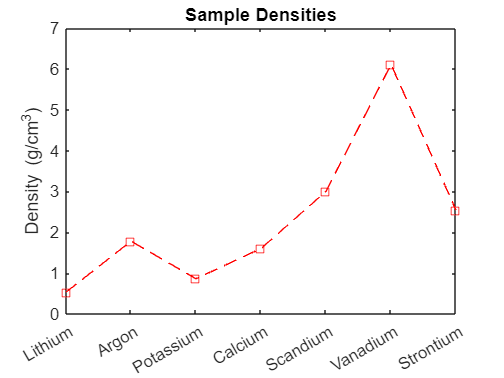

if doPlot==1
    plot(density, "r--s")
    title("Sample Densities")
    xticklabels(Elements.Element)
    ylabel("Density (g/cm^3)")
else
    
    disp("The density of " + Elements.Element + " is " + density)
end

**Further Practice**

Try executing your code a few times using the  Run button to see the behavior of your if block.

To add more conditions to your if block, use the elseif keyword after the if statement. You can include multiple elseif blocks. You can also omit the else block.

if condition1 

   code 

elseif condition2

   code 

else

   code

end

Try adding a variable doDisplay to determine if the densities should be displayed. Add this condition by replacing the else block with an elseif block.

What happens when doPlot and doDisplay both equal 1? What happens when they both equal 0, or when only doDisplay equals 1?

doDisplay=randi([0,1])
if doPlot==1
    plot(density)
    title("Sample Densities")
    xticklabels(Element)
    ylabel("Density (g/cm^3)")
elseif doDisplay==1
    disp(density)
    
end